**3D Transformations**

**Observing the Impact of Transformation Order**

While working with geometric transformations, I realized that the order in which transformations are applied significantly affects the final position and shape of an object. To explore this, I decided to experiment with a simple square by changing the sequence of transformations—rotation, scaling, and translation—and observing how the outcomes differ.

I began by applying the transformations in the order of rotate, scale, and translate. I expected the rotation to take effect first, orienting the square at an angle. Then, the scaling would stretch the rotated square, and the translation would finally shift it to a new position. To visualize this, I plotted the transformed square in green. The sequence created a dynamic and intuitive result, where the rotation clearly influenced how the scaling affected the square's shape.

Next, I switched the order to scale, rotate, and translate. This time, I scaled the square first, changing its dimensions without altering its orientation. After that, I rotated the scaled square and then translated it. I plotted this transformed square in yellow, and the result was distinctly different. The scaling now applied uniformly across the original square, with the rotation acting on the stretched shape rather than the original one.

These experiments showed me how sensitive geometric transformations are to their order. By visualizing these changes, I gained a deeper understanding of the interplay between rotation, scaling, and translation. It reinforced my appreciation for how transformations build on one another and how a simple change in sequence can produce entirely different outcomes.

% Now, I am going to experiment by changing the order of transformations.
% This will help me observe how the order affects the final position and shape of the square.

%% Plotting the Green Square
% First, I apply the transformations in the order: Rotate -> Scale -> Translate.
% I expect the rotation to happen first, followed by scaling, and finally the translation.
HrectRST = R * S * T; % Combining transformations: Rotate -> Scale -> Translate
GreenSQ = line([square(:,1); square(1,1)], [square(:,2); square(1,2)], ...
    'Color', 'g', 'LineWidth', 3); % Plotting the square with a green color
% I apply the transformation matrix to the axes.
AxesTransformation = hgtransform('Parent', gca, 'matrix', HrectRST);
% I set the green square as a child of the transformed axes.
set(GreenSQ, 'Parent', AxesTransformation);

%% Plotting the Yellow Square
% Next, I change the order of transformations to Scale -> Rotate -> Translate.
% This means the square will first scale, then rotate, and finally translate.
HrectSRT = S * R * T; % Combining transformations: Scale -> Rotate -> Translate
YellowSQ = line([square(:,1); square(1,1)], [square(:,2); square(1,2)], ...
    'Color', 'y', 'LineWidth', 3); % Plotting the square with a yellow color
% I apply the transformation matrix to the axes.
AxesTransformation = hgtransform('Parent', gca, 'matrix', HrectSRT);

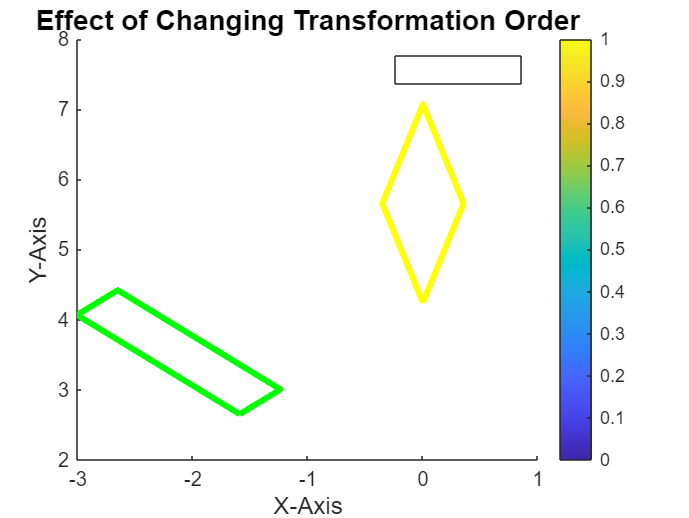

% I set the yellow square as a child of the transformed axes.
set(YellowSQ, 'Parent', AxesTransformation);

% Final adjustments
% I ensure the title and axis labels reflect the new transformations.
title('Effect of Changing Transformation Order', 'FontSize', 14, 'FontWeight', 'bold');
xlabel('X-Axis', 'FontSize', 12);
ylabel('Y-Axis', 'FontSize', 12);
legend({'Green Square (Rotate -> Scale -> Translate)', ...
        'Yellow Square (Scale -> Rotate -> Translate)'}, ...
        'Location', 'NorthEast', 'FontSize', 10); % Adding a legend to explain the colors